# Part 6: 最適潮流計算と定態安定度制約付き OPF

潮流計算は「発電機がこの出力を出したら、電圧と潮流はどうなるか」に答えます。しかし運用者は、まず出力そのものを決めなければなりません。この Part では、同じ需要をいちばん安くまかなう出力の決め方を、IEEE 9 母線系統で順に組み立てます。まず送電線を考えない経済負荷配分（ELD）、次に電力方程式と運転の制約を入れた最適潮流計算（OPF）、さらに線路がいっぱいになったときの母線ごとの価格（LMP）、最後に、安い運転点が揺れやすくなる問題と、固有値の条件を付けた OPF です。

**この Part で分かること**

- 経済負荷配分の問題と、最適な配分で増分費用がそろう理由（手計算で GUILDA の答えを確かめます）

- AC OPF の定式化と、損失・電圧の上限が答えをどう変えるか

- 地点別限界価格（LMP）の意味と、線路の混雑で価格が母線ごとに分かれる理由（負荷を少し増やして確かめます）

- 安い運転点ほど減衰が小さくなり得る理由と、OPF・線形化・固有値の感度を繰り返す安定度制約付き OPF の解き方

知識ページ: [Part 6: 最適潮流計算と定態安定度制約付き OPF](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part6-optimal-power-flow.html","-browser")) （クリックするとブラウザで開きます）。知識ページの図は、このライブスクリプトの中のコードで描いています。

**注意:** GUILDA のフォルダがパスに入っている（`GUILDA.addpath` を実行済みの）状態で実行します。Optimization Toolbox を使います。全体の実行には 1〜2 分かかります（安定度制約付き OPF の 2 回の計算が大半です）。

## 1. 系統モデルと費用・制約を用意する

同梱の IEEE 9 母線系統を使います。母線 1〜3 に発電機 G1〜G3、母線 5・6・8 に負荷（合計 315 MW）があります。OPF に必要なのは、発電の費用と、守るべき制約です。

火力発電機の燃料費は、ふつう出力の 2 次関数で表します。GUILDA では、機器 $g$ の費用を次のように書きます。


$$C_g(P_g, Q_g) = H_{P,g}P_g^2 + f_{P,g}P_g + H_{Q,g}Q_g^2 + f_{Q,g}Q_g$$


$P_g$、$Q_g$ は機器が系統へ送り出す有効電力と無効電力で、単位法（基準 100 MVA）です。費用の単位は $/h です。係数は機器のパラメータの `OPF` のグループの `HP`、`fP`、`HQ`、`fQ` にあります。`get_parameter` で、3 台の発電機（Key `"gen-1axis"`）の係数を表で取り出します。

net = network.IEEE9bus(LocalController=true);
tab_cost = net.get_parameter("OPF", Key="gen-1axis")

tab_cost = 3×8 table
               P0    Q0    HP    HQ    fP    fQ    startup    shutdown
               __    __    __    __    __    __    _______    ________

    B001SG1    0     0     1     0     1     0        0          0    
    B002SG1    0     0     1     0     1     0        0          0    
    B003SG1    0     0     1     0     1     0        0          0    


同梱の値は 3 台とも同じで比べがいがないので、知識ページと同じく MATPOWER の 9 母線のケースの係数（定数項を除く）を表に書き込み、`set_parameter` で系統に戻します。無効電力の費用は 0 のままです。

HP = [1100, 850, 1225];   % H_P [$/h/pu^2]（G1, G2, G3）
fP = [ 500, 120,  100];   % f_P [$/h/pu]
tab_cost.HP = HP';
tab_cost.fP = fP';
net.set_parameter("OPF", tab_cost);

母線電圧の上下限は、既定の 0.5〜1.5 pu から、運用でよく使う 0.9〜1.1 pu に狭めます。制約は母線・機器・ブランチのパラメータの `operation` のグループにあります。

tab_V = net.get_parameter("operation", Class="Bus");
tab_V.Vmin(:) = 0.9;
tab_V.Vmax(:) = 1.1;
net.set_parameter("operation", tab_V);
net.get_opf_condition();

Bus
            Vmin    Vmax    Gshunt    Bshunt     Type        V      Varg
            ____    ____    ______    ______    _______    _____    ____

    B001    0.9     1.1       0         0       "slack"     1.04     0  
    B002    0.9     1.1       0         0       "PV"       1.025     0  
    B003    0.9     1.1       0         0       "PV"       1.025     0  
    B004    0.9     1.1       0         0       "PQ"           1     0  
    B005    0.9     1.1       0         0       "PQ"           1     0  
    B006    0.9     1.1       0         0       "PQ"           1     0  
    B007    0.9     1.1       0         0       "PQ"           1     0  
    B008    0.9     1.1       0         0       "PQ"           1     0  
    B009    0.9     1.1       0         0       "PQ"           1     0  

Component
                 Bus       HP     fP     HQ    fQ     P0       Q0      Pmin     Pmax     Qmin     Qmax 
                ______    ____    ___    __    __    _____    _____    _____ 

`Bus` は母線の電圧の上下限、`Component` は機器の費用の係数と出力の上下限、`Branch` はブランチの容量（`Pmax`、`Qmax`、`Imax`、`Smax`、`Vargmax`）です。発電機の出力には上下限がなく（`-Inf`〜`Inf`）、負荷は上限と下限が同じ値なので、その電力のまま固定されます。上下限を `Inf`（下限は `-Inf`）にした制約はかかりません。

図は、知識ページの図と同じ配色と大きさで描きます。色と、図を作るときの設定（白い背景、幅 18 cm、文字 8 pt）を最初にまとめておきます。

sct_style = struct( ...
    "rr_brand", [0, 89, 167] / 255, ...    % 青（主な系列）
    "rr_c2",    [46, 107, 63] / 255, ...   % 緑
    "rr_c3",    [154, 91, 0] / 255, ...    % 橙（比べる場合）
    "rr_ink",   [27, 33, 39] / 255, ...    % 濃い文字
    "rr_ink2",  [56, 66, 76] / 255, ...    % 軸と文字
    "rr_muted", [90, 101, 112] / 255, ...  % 補助の線
    "rr_tint",  [238, 243, 248] / 255);    % 範囲の帯
c_fig = {"Color", "w", "Units", "centimeters", "DefaultAxesFontSize", 8, ...
    "DefaultTextFontSize", 8, "DefaultLegendFontSize", 8, "DefaultLegendFontSizeMode", "manual"};

## 2. 経済負荷配分：需要をいちばん安く割り振る

### 問題

まず送電線を考えず、発電の合計が需要の合計 $P_\mathrm{D}$ に等しいことだけを条件にします。これを経済負荷配分（ELD）といいます。


$$\min_{P_1,\dots,P_n} \sum_i C_i(P_i) \quad \text{s.t.} \quad \sum_i P_i = P_\mathrm{D}, \quad P_i^\mathrm{min} \le P_i \le P_i^\mathrm{max}$$


### 等増分費用の条件

傾き $\mathrm{d}C_i/\mathrm{d}P_i$ を増分費用（限界費用）といいます。その発電機で出力をもう 1 単位増やすのにかかる費用です。上下限に達した発電機がなければ、ラグランジュ関数 $L = \sum_i C_i(P_i) - \lambda(\sum_i P_i - P_\mathrm{D})$ を $P_i$ で微分して 0 とおくと、最適な配分では、すべての発電機の増分費用が等しくなります。


$$\frac{\mathrm{d}C_i}{\mathrm{d}P_i}(P_i) = 2H_{P,i}P_i + f_{P,i} = \lambda \qquad (i = 1, \dots, n)$$


1 台だけ増分費用が安ければ、その発電機に少し出力を移すと総費用が下がるので、最適ではありません。これが等増分費用の考え方です。上限に達した発電機の増分費用は $\lambda$ 以下、下限に達した発電機は $\lambda$ 以上になります。

費用が 2 次関数なら、上の式から $P_i = (\lambda - f_{P,i})/(2H_{P,i})$ です。これを $\sum_i P_i = P_\mathrm{D}$ に入れると、$\lambda$ が手で求まります。


$$\lambda = \frac{P_\mathrm{D} + \sum_i f_{P,i}/(2H_{P,i})}{\sum_i 1/(2H_{P,i})}$$


### GUILDA で解いて、手計算と比べる

`Method="ELD"` で経済負荷配分を解きます。

resELD = net.calculate_optimal_powerflow(Method="ELD");
resELD.disp_summary();

Optimal power flow of PowerNetwork (ELD, quadprog): solved, flag 1
- Calculation: 1 iterations, elapsed 4.09 s
- Cost: 4131.03
- Generation: P = 3.1500 pu
- Load: P = 3.1500 pu
- Losses: P = -0.0000 pu
- Binding constraints: 0 (branch limits 0)
- LMP: 2404.42 at B001 to 2404.42 at B001 (cost per pu)


同じ答えを、上の式から手で求めます。$P_\mathrm{D}$ は 3 つの負荷の合計（3.15 pu）です。

sv_gen = ["B001SG1", "B002SG1", "B003SG1"];
sct_ELD = resELD.get_summary();
P_D = sct_ELD.r_Pload                                    % [pu] 負荷の合計

P_D = 3.1500

lambda_hand = (P_D + sum(fP ./ (2*HP))) / sum(1 ./ (2*HP))   % [$/h/pu]

lambda_hand = 2.4044e+03

P_hand_MW = 100 * (lambda_hand - fP) ./ (2*HP)           % [MW] 手計算の出力（G1, G2, G3）

P_hand_MW =    86.5645  134.3776   94.0579


P_GUILDA_MW = 100 * resELD.tab_cub{sv_gen, "P"}'         % [MW] GUILDA の出力

P_GUILDA_MW =    86.5645  134.3776   94.0579


dCdP_MWh = (2*HP .* P_hand_MW/100 + fP) / 100            % [$/MWh] 手計算の出力での増分費用

dCdP_MWh =    24.0442   24.0442   24.0442


手計算と GUILDA の出力は一致し、3 台の増分費用はどれも $\lambda \approx 2404$ $/h/pu です。GUILDA の LMP（`get_lmp`）もどの母線でも同じこの値で、ELD の $\lambda$ に当たります。単位は単位法の電力あたり（$/h/pu）なので、100 で割ると $/MWh になり、約 24.0 $/MWh です。総費用は約 4131 $/h です。

増分費用の直線と $\lambda$ を図にします（知識ページの「経済負荷配分」の図）。水平な線 $\lambda$ を上下させ、3 台の出力の合計が需要に等しくなる高さで止めると、それぞれの直線との交点が配分です。

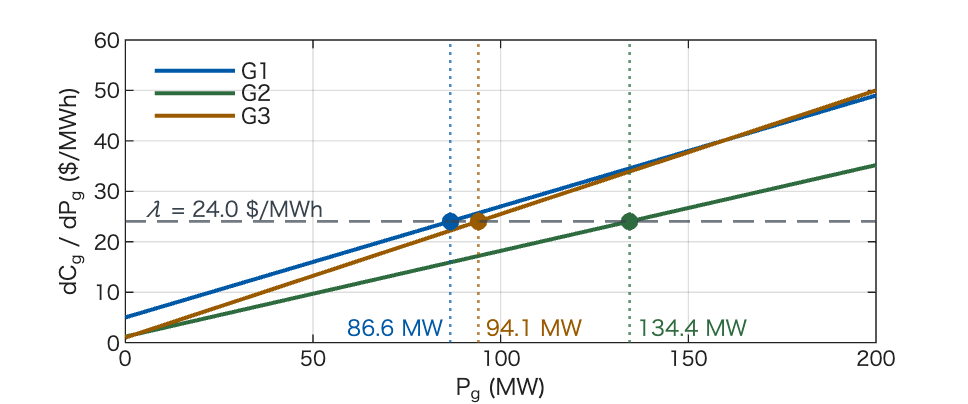

r_lambda = sct_ELD.r_LMPmax / 100;           % [$/MWh]（LMP はどの母線も同じ）
rv_Pg = 100 * resELD.tab_cub{sv_gen, "P"};    % [MW]
rv_P = linspace(0, 200, 2);                   % [MW]
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
ax = axes(fig, XLim=rv_P, YLim=[0, 60], NextPlot="add", XGrid="on", YGrid="on", Box="on");
rm_color = [sct_style.rr_brand; sct_style.rr_c2; sct_style.rr_c3];
for k = 1:3
    plot(ax, rv_P, (2 * HP(k) * rv_P / 100 + fP(k)) / 100, Color=rm_color(k, :), LineWidth=1.5, ...
        DisplayName=sprintf("G%d", k));
end
yline(ax, r_lambda, "--", Color=sct_style.rr_ink2, LineWidth=1, HandleVisibility="off");
text(ax, 4, r_lambda + 2.2, sprintf("\\lambda = %.1f $/MWh", r_lambda), Color=sct_style.rr_ink2);
for k = 1:3
    plot(ax, rv_Pg(k), r_lambda, "o", MarkerSize=6, Color=rm_color(k, :), ...
        MarkerFaceColor=rm_color(k, :), HandleVisibility="off");
    xline(ax, rv_Pg(k), ":", Color=rm_color(k, :), LineWidth=1, HandleVisibility="off");
    if rv_Pg(k) == min(rv_Pg)   % G1 と G3 は近いので、G1 は線の左に書く
        text(ax, rv_Pg(k) - 2, 3, sprintf("%.1f MW", rv_Pg(k)), Color=rm_color(k, :), HorizontalAlignment="right");
    else
        text(ax, rv_Pg(k) + 2, 3, sprintf("%.1f MW", rv_Pg(k)), Color=rm_color(k, :));
    end
end
xlabel(ax, "P_g (MW)");
ylabel(ax, "dC_g / dP_g ($/MWh)");
legend(ax, Location="northwest", Box="off");

**考察:** 直線の切片 $f_{P,g}$ がいちばん大きい G1 は、出力 0 でも増分費用が 5 $/MWh と高く、配分は約 87 MW にとどまります。切片の小さい G2 は、傾き $2H_{P,g}$ も小さいので、いちばん多い約 134 MW を受け持ちます。需要が増えると $\lambda$ の線が上がり、傾きの小さい発電機ほど多く出力を増やします（増える量は $1/(2H_{P,g})$ に比例します）。この例の発電機には出力の上下限がないので、すべての発電機が同じ $\lambda$ で運転しています。

## 3. ネットワークと制約を加える：AC OPF

### 定式化

経済負荷配分は、発電機や負荷がどこにあるかを知りません。実際には、電力は送電線を通って運ばれ、途中で一部が失われ（損失）、送れる量にも限りがあります。最適潮流計算（OPF）は、同じ費用を、電力方程式と運転の制約の下で最小にします。GUILDA が解く AC OPF は次のとおりです。


$$\begin{aligned} \min_{V,P_g,Q_g}\quad & \sum_g C_g(P_g, Q_g) \\ \text{s.t.}\quad & V_i \sum_k \overline{Y_{ik} V_k} = \sum_{g \in i} (P_g + jQ_g) \quad \text{at every bus } i \\ & P_g^\mathrm{min} \le P_g \le P_g^\mathrm{max}, \quad Q_g^\mathrm{min} \le Q_g \le Q_g^\mathrm{max} \\ & V_i^\mathrm{min} \le |V_i| \le V_i^\mathrm{max} \\ & |P_e| \le P_e^\mathrm{max},\quad  |Q_e| \le Q_e^\mathrm{max},\quad  |I_e| \le I_e^\mathrm{max},\quad  P_e^2 + Q_e^2 \le (S_e^\mathrm{max})^2,\quad  |\theta_\mathrm{from} - \theta_\mathrm{to}| \le \theta^\mathrm{max} \end{aligned}$$


$V_i = |V_i|e^{j\theta_i}$ は母線 $i$ の電圧フェーザ（slack 母線の角度は 0 に固定）、$Y$ はアドミタンス行列、上の横線は複素共役です。1 つ目の制約は各母線の電力方程式（潮流計算と同じ式）で、損失と、電力が送電線にどう分かれて流れるかが、ここに入ります。$P_g$、$Q_g$ は機器 $g$ が注入する電力で、負荷は負の値に固定されています。ブランチの制約は、すべてのブランチの両端 $e$ にかかります。未知数は電圧の大きさと角度、発電機の出力だけで、答えは潮流計算の解そのものです。

### 解く

resAC = net.calculate_optimal_powerflow(Method="AC OPF");
resAC.disp_summary();

Optimal power flow of PowerNetwork (AC OPF, fmincon): solved, flag 1
- Calculation: 21 iterations, elapsed 13.8 s
- Cost: 4211.69
- Generation: P = 3.1831 pu, Q = -0.0964 pu
- Load: P = 3.1500 pu, Q = 1.1500 pu
- Losses: P = 0.0331 pu, Q = -1.2464 pu
- Binding constraints: 9 (branch limits 0)
- LMP: 2403.45 at B002 to 2499.85 at B005 (cost per pu)


ELD と AC OPF の費用と損失を比べます。`get_summary` は、`disp_summary` が表示する値を構造体で返します。損失（`r_Ploss`）は、すべての母線の注入電力の和です。

sct_AC = resAC.get_summary();
P_loss_MW = 100 * sct_AC.r_Ploss

P_loss_MW = 3.3067

dCost = sct_AC.r_cost - sct_ELD.r_cost

dCost = 80.6596

mean_lmp = mean(resAC.get_lmp().LMP) / 100                      % [$/MWh]

mean_lmp = 24.4426

cost_of_loss = P_loss_MW * mean_lmp                             % [$/h] 損失を平均の LMP で買う費用

cost_of_loss = 80.8240

**考察:** AC OPF の費用は ELD より約 81 $/h 高くなります。発電機は約 3.3 MW の損失もまかなう必要があるからです。損失を平均の LMP（約 24.4 $/MWh）で買うとおよそ 81 $/h で、費用の差は、ほぼ損失をまかなう分だと分かります。

どの制約が効いているか（等号で成り立っているか）を一覧にします。

resAC.disp_binding();

Binding constraints (9) of the OPF result of PowerNetwork
       Constraint       Object      Value       Limit    Multiplier 
    ________________    ______    __________    _____    ___________

    "Vmax"              "B001"           1.1     1.1          8.2165
    "Vmax"              "B007"           1.1     1.1          77.568
    "Vmax"              "B009"           1.1     1.1          75.431
    "balancedP_B004"    ""        2.5535e-15       0         -2475.6
    "balancedQ_B004"    ""        1.7375e-14       0        -0.43212
    "balancedP_B007"    ""        2.2204e-16       0         -2403.5
    "balancedQ_B007"    ""        2.9213e-15       0     -7.8681e-06
    "balancedP_B009"    ""        4.4409e-16       0         -2407.6
    "balancedQ_B009"    ""        1.1727e-14       0     -1.9206e-06



母線 B001・B007・B009 の電圧が上限 1.1 pu に張り付いています。同じ電力なら、電圧を高くすると電流が小さくなり、損失（電流の 2 乗に比例）が減るからです。電圧の上限を広げれば、さらに少し安くなります。`balancedP_` と `balancedQ_` は各母線の電力のつり合いの式で、その乗数（`Multiplier`）の符号を変えたものが、次の節の LMP です。

**注意:** `Method="DC OPF"` は、電圧の大きさをすべて 1 pu とし、損失を無視する近似です。線路容量の制約は残したまま、ずっと解きやすい問題になるので、電力市場など速さが求められる場面で広く使われます。`Method` を省くと `GUILDA.setting` の既定値（`"AC OPF"`）で解きます。`Verbose=true` にするとソルバーの途中経過を表示します。

## 4. 地点別限界価格（LMP）

### 定義

経済負荷配分の $\lambda$ には便利な意味があります。需要が 1 単位増えたときに、最小の総費用がどれだけ増えるかです。OPF は、この数を母線ごとに与えます。母線 $i$ の地点別限界価格（LMP）は、その母線の負荷 $P_{\mathrm{D},i}$ だけを 1 単位増やしたときに、すべての制約を守ったままの最小費用 $C^{\ast}$ がどれだけ増えるかです。


$$\mathrm{LMP}_i = \frac{\partial C^{\ast}}{\partial P_{\mathrm{D},i}}$$


この値は、最適解での母線 $i$ の有効電力のつり合いの式のラグランジュ乗数に等しく、GUILDA もそこから求めます。`get_lmp` は、LMP を 3 つの部分に分けて返します。


$$\mathrm{LMP}_i = \underbrace{\lambda_\mathrm{ref}}_{\text{energy}} + \underbrace{\mathrm{LMP}_i^\mathrm{cong}}_{\text{congestion}} + \underbrace{\mathrm{LMP}_i^\mathrm{loss}}_{\text{loss}}$$


エネルギー分は基準母線（既定は slack 母線の B001）の価格で、どこでも同じです。損失分は、その母線の負荷が増えると損失が増えるか減るか、混雑分は効いている制約の影響を表します。

lmpAC = resAC.get_lmp()

lmpAC = 9×4 table
             LMP      Energy    Congestion     Loss  
            ______    ______    __________    _______

    B001    2475.6    2475.6           0            0
    B002    2403.5    2475.6     -8.0475      -64.074
    B003    2407.6    2475.6     -5.6819      -62.299
    B004    2475.6    2475.6      3.9622      -3.9437
    B005    2499.8    2475.6      7.6557       16.621
    B006    2499.8    2475.6      6.4456        17.83
    B007    2403.5    2475.6     -2.2321      -69.889
    B008    2425.4    2475.6      0.9688      -51.151
    B009    2407.6    2475.6     -1.8165      -66.164


線路容量の制約が効いていないので、混雑分は小さく、違いは主に損失分によるものです。どの母線も 2400〜2500 $/h/pu（24〜25 $/MWh）に収まっています。G2 に近い B002・B007 は、そこで負荷が増えても電力を遠くへ運ばずに済むので、損失分が負（安い）になっています。系統図の上に色で描きます。

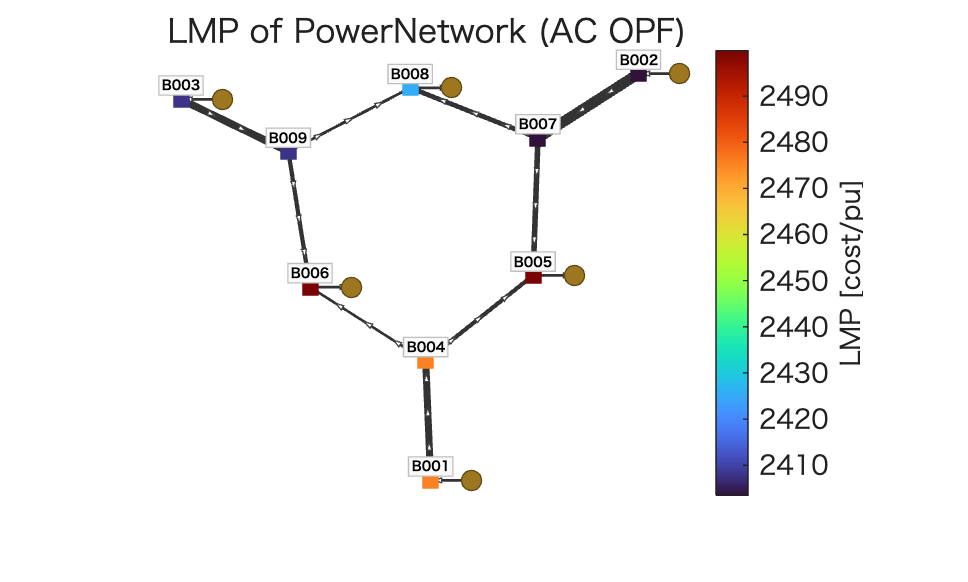

resAC.plot_lmp();

**注意:** 内訳は基準母線（`get_lmp` の `ReferenceBus`）の価格をエネルギー分とした分け方です。基準母線を変えると内訳も変わりますが、LMP そのものは変わりません。

## 5. 線路の混雑で価格が分かれる

### 線路容量を下げる

安い G2 の近くにある線路 EL008（母線 7–8）の有効電力の上限を 40 MW（0.4 pu）にして、もう一度 AC OPF を解きます。まず、制限がないときにこの線路を流れている電力を見ておきます（母線 7 側の端の値）。

P_EL008_MW = 100 * abs(resAC.tab_cub{"EL008_B007", "P"})

P_EL008_MW = 62.2096

tab_line = net.get_parameter("operation", Class="Branch");
tab_line{"EL008", "Pmax"} = 0.4;
net.set_parameter("operation", tab_line("EL008", "Pmax"));
resCong = net.calculate_optimal_powerflow(Method="AC OPF");
resCong.disp_summary();

Optimal power flow of PowerNetwork (AC OPF, fmincon): solved, flag 1
- Calculation: 18 iterations, elapsed 12 s
- Cost: 4393.88
- Generation: P = 3.1852 pu, Q = -0.0217 pu
- Load: P = 3.1500 pu, Q = 1.1500 pu
- Losses: P = 0.0352 pu, Q = -1.1717 pu
- Binding constraints: 8 (branch limits 1)
- LMP: 1887.01 at B002 to 3376.58 at B008 (cost per pu)


resCong.disp_binding(Kind="Branch");

Binding constraints (1) of the OPF result of PowerNetwork
         Constraint            Object       Value    Limit    Multiplier
    ____________________    ____________    _____    _____    __________

    "Pmax_EL008_B007(2)"    "EL008_B007"     0.4      0.4       1639.9  



線路 EL008 の母線 B007 側の潮流が上限 0.4 pu に張り付き（`Pmax_EL008_B007`）、費用は約 4394 $/h に上がりました。

3 つの場合の出力を、費用と損失とともに並べます（知識ページの「制約を加えた OPF」の図）。

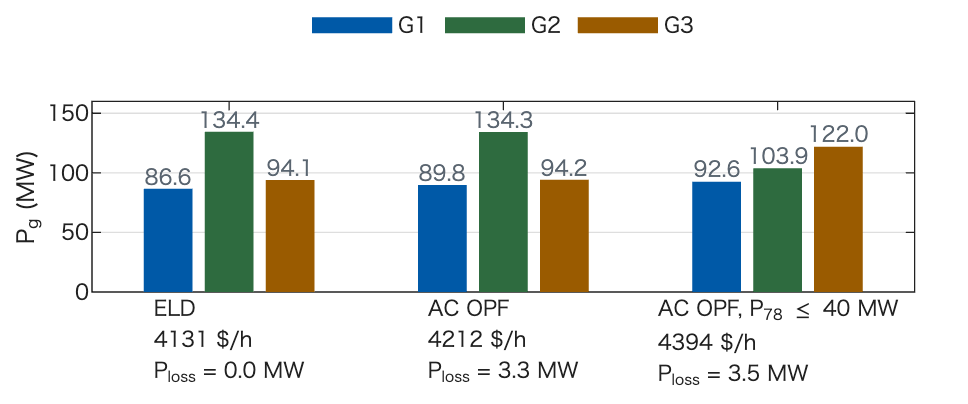

c_res = {resELD, resAC, resCong};
sr_case = ["ELD", "AC OPF", "AC OPF, P_{78} \leq 40 MW"];
rm_P = zeros(3, 3);
sr_tick = strings(1, 3);
for i_c = 1:3
    res = c_res{i_c};
    rm_P(i_c, :) = 100 * res.tab_cub{sv_gen, "P"};
    sct = res.get_summary();
    r_loss = abs(100 * sct.r_Ploss);              % [MW]（ELD の "-0.0" を避けるため abs）
    sr_tick(i_c) = sprintf("%s\\newline%.0f $/h\\newlineP_{loss} = %.1f MW", sr_case(i_c), sct.r_cost, r_loss);
end
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
tl = tiledlayout(fig, 1, 1, Padding="compact");
ax = nexttile(tl);
set(ax, XLim=[0.5, 3.5], YLim=[0, 160], XTick=1:3, XTickLabel=sr_tick, XTickLabelRotation=0, FontSize=8, ...
    NextPlot="add", YGrid="on", Box="on");
b = bar(ax, 1:3, rm_P, 0.8, EdgeColor="none");
for k = 1:3
    b(k).FaceColor = rm_color(k, :);
    b(k).DisplayName = sprintf("G%d", k);
    text(ax, b(k).XEndPoints, b(k).YEndPoints + 1, compose("%.1f", rm_P(:, k)), ...
        HorizontalAlignment="center", VerticalAlignment="bottom", Color=sct_style.rr_muted);
end
ylabel(ax, "P_g (MW)");
lg = legend(ax, b, Orientation="horizontal", Box="off");
lg.Layout.Tile = "north";

**考察:** 線路 7–8 を 40 MW に制限すると、その近くの安い G2 は、その線路を通して母線 8 へ電力を送れなくなります。G2 の出力は約 134 MW から約 104 MW に下がり、反対側にある高い G3 が約 122 MW に増えて補います。費用は AC OPF より約 4% 上がります。等増分費用の条件はもう成り立たず、G2 と G3 の増分費用は、それぞれ約 18.9 $/MWh と約 30.9 $/MWh に大きく離れます（$2H_{P,g}P_g + f_{P,g}$ から計算できます）。

### 母線ごとの価格

lmpCong = resCong.get_lmp()

lmpCong = 9×4 table
             LMP      Energy    Congestion     Loss  
            ______    ______    __________    _______

    B001    2536.8    2536.8           0            0
    B002      1887    2536.8      -591.8      -57.996
    B003    3088.8    2536.8      627.31      -75.313
    B004    2536.8    2536.8      4.9262      -4.9262
    B005    2358.3    2536.8     -195.91       17.398
    B006    2784.3    2536.8      231.48       15.977
    B007    1887.6    2536.8     -585.58       -63.62
    B008    3376.6    2536.8      892.01      -52.239
    B009    3088.8    2536.8      631.96      -79.964


系統図の上に描きます（知識ページの「混雑と LMP」の図）。効いている線路（EL008）が強調されます。

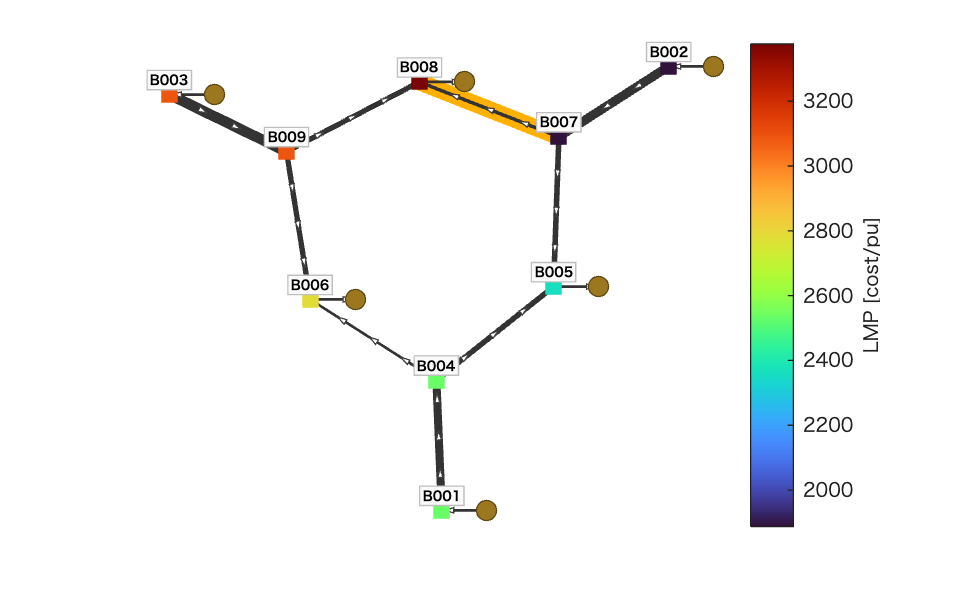

fig = figure(c_fig{:}, Position=[2, 2, 18, 11]);
ax = axes(fig);
resCong.plot_lmp(Parent=ax);
title(ax, "");
axis(ax, "off");

**考察:** 混雑すると価格が分かれます。G2 の側の B002・B007 は約 18.9 $/MWh に下がり、いっぱいの線路の先の B008 は約 33.8 $/MWh、G3 のある B003・B009 は約 30.9 $/MWh です。B008 の価格は、どの発電機の増分費用（最大の G3 で約 31 $/MWh）よりも高くなっています。混雑分（`Congestion`）を見ると、この差がほとんど線路の制約から来ていることが分かります。

### LMP の定義を確かめる：負荷を少し増やして解き直す

「B008 の価格がどの発電機より高い」のはなぜでしょうか。LMP の定義どおり、B008 の負荷だけを 1 MW（0.01 pu）増やして解き直し、最小費用の増え方と、各発電機の出力の変化を見ます。負荷の電力は、パラメータの `powerflow` のグループの `P` です（負は消費）。`Owner="B008"` で母線 8 の下にある機器だけを取り出します。

tab_load8 = net.get_parameter("powerflow", Owner="B008")    % 母線 8 の負荷（B008LRX1）

tab_load8 = 1×2 table
                P       Q  
                __    _____

    B008LRX1    -1    -0.35


tab_plus = tab_load8;
tab_plus.P = tab_load8.P - 0.01;              % 100 MW → 101 MW
net.set_parameter("powerflow", tab_plus);
resPlus = net.calculate_optimal_powerflow(Method="AC OPF");
net.set_parameter("powerflow", tab_load8);    % 元に戻す
dCdP = (resPlus.get_summary().r_cost - resCong.get_summary().r_cost) / 0.01 / 100     % [$/MWh] 費用の増え方

dCdP = 33.9285

LMP_B008 = lmpCong{"B008", "LMP"} / 100                   % [$/MWh] get_lmp の値

LMP_B008 = 33.7658

dP_gen_MW = 100 * (resPlus.tab_cub{sv_gen, "P"} - resCong.tab_cub{sv_gen, "P"})'

dP_gen_MW =     0.3790   -0.3827    1.0159


**考察:** 費用の増え方は約 33.9 $/MWh で、`get_lmp` の値（約 33.8 $/MWh）とほぼ一致します（差は 1 MW という有限の幅によるものです）。出力の変化を見ると、1 MW の負荷の増加に対して G3 が約 1.0 MW 上がり、同時に安い G2 が約 0.4 MW **下がって**います。いっぱいの線路 7–8 の潮流を上限のままに保つには、母線 8 へ流れ込む分を G2 から G3 へ付け替えなければならないからです。高い G3 を上げ、安い G2 を下げるので、1 MW の費用は G3 の増分費用よりも高くなります。

地点別の価格を使う電力市場では、この価格の差が、新しい送電線や発電所がどこで最も役に立つかを知らせる信号になります。この例なら、線路 7–8 を太くするか、母線 8 の近くに発電所を置くと費用が下がります。

次の節のために、線路の上限を元に戻します。

tab_line{"EL008", "Pmax"} = Inf;
net.set_parameter("operation", tab_line("EL008", "Pmax"));

## 6. 安い運転ほど揺れやすくなり得る

OPF が見ているのは、1 つの定常状態だけです。系統が乱されたときにどうなるかは考えていません。ところが、いちばん安い点は物事を限界まで押しやりがちです。送電線は多くの電力を運び、その両端の位相差 $\delta$ は大きくなり、出力は安い少数の発電機に集まります。

2 つの母線を結ぶ送電線（リアクタンス $X$）で送る電力と、その位相差に対する傾きは次のとおりです。


$$P = \frac{V_1V_2}{X}\sin\delta, \qquad \frac{\partial P}{\partial \delta} = \frac{V_1V_2}{X}\cos\delta$$


発電機どうしは、この傾き（同期化力）で、ばねでつながれた重りのように結び付いています。送る電力が大きいほど $\delta$ は大きくなり、$\cos\delta$ が小さくなるので「ばね」が弱くなります。大きな電力を送っているときは、AVR と回転子の揺れとの関係も変わり、減衰が小さくなることがあります。

これを調べるには、近似線形化を使います。運転点のまわりの小さな揺れは、線形モデルの固有値 $\lambda = \sigma \pm j\omega$ に対応するモードの重ね合わせです。$\sigma \lt 0$ ならモードは収まり、周波数 $f = \omega/2\pi$ で振動します。ダンピング比 $\zeta$ は、振動の速さに比べて揺れがどれだけ早く収まるかを表します。


$$\zeta = \frac{-\sigma}{\sqrt{\sigma^2 + \omega^2}}$$


GUILDA の OPF は、潮流計算・時間シミュレーション・近似線形化と同じ系統モデルを使うので、OPF の解の運転点で、そのまま固有値を調べられます。動特性のモデル（発電機と AVR・PSS）を使うので、先に `initialize` で系統の平衡点を求めておきます。`MinDampingRatio=0` を付けると、最初の OPF の解がすでに条件（$\zeta \ge 0$）を満たすので、通常の AC OPF を 1 回解き、その解の固有値を調べるだけになります。

net.initialize();
resFree = net.calculate_optimal_powerflow(Method="AC OPF", MinDampingRatio=0);
tab_modeFree = resFree.sct_stability.tab_mode;
tab_modeFree(tab_modeFree.Frequency > 0, :)

ans = 5×4 table
        Eigenvalue        Frequency    DampingRatio       Owner    
    __________________    _________    ____________    ____________

     -100.14+0.016933i     0.002695             1      "B002SG1CP2"
     -66.471+0.023924i    0.0038076             1      "B002SG1CP2"
    -0.35473+8.7741i         1.3964      0.040396      "B003SG1"   
    -0.25935+4.5216i        0.71963      0.057265      "B002SG1"   
    -0.50683+0.42428i      0.067526       0.76679      "B001SG1"   


費用は 3 節の AC OPF と同じ約 4212 $/h です。振動モードのうち、いちばん減衰の小さいものは、主に G3（B003SG1）が揺れる約 1.4 Hz のモードで、ダンピング比は約 4.04% です。`Owner` は、そのモードにいちばん大きく参加している機器や制御器です。運用では、すべてのモードに数 % 程度の最小のダンピング比を求めることがよくあります。ここでは、それを 4.2% とします。すると問いは、すべてのモードの減衰を 4.2% 以上に保ちながら、いちばん安い運転点はどこか、になります。

## 7. 固有値の条件を付けた OPF

### 外側の反復

素直な答えは、OPF に「すべてのダンピング比 $\ge \zeta_\mathrm{min}$」という条件を加えることです。これを定態安定度（小信号安定度）制約付き OPF といいます。難しいのは、ダンピング比が出力の簡単な式ではないことです。運転点での線形モデルと、その固有値を求めなければ分かりません。そこで GUILDA は、次の手順を繰り返し、OPF そのものには固有値を計算させません。

- OPF を解く（1 回目は通常の AC OPF）。

- その解の運転点で系統を線形化し、固有値とダンピング比を求める。

- すべてのモードが条件を満たしていれば終わる。

- 下限に近いモードについて、設定値を少し動かしたときのダンピング比の変化（感度）から、線形の制約を作る。

- その制約を加えて、1. に戻る。

手順 4. の設定値 $u$ は、発電機の出力 $P$（slack 母線の発電機は除きます。その $P$ は潮流で決まるからです）と、発電機のある母線の電圧の大きさ $|V|$ です。傾き $\nabla\zeta_m$ は、それぞれを少し動かして線形化し直して求めます。これを使って、今の点 $u_k$ の近くのダンピング比を平面で置き換え、次の回の OPF に次の制約を加えます。


$$\zeta_m(u_k) + \nabla\zeta_m(u_k)^{\top}(u - u_k) \quad \ge\quad  \zeta_\mathrm{min} + \zeta_\mathrm{margin}, \qquad |u_j - u_{k,j}| \le \Delta_{k,j}$$


$\zeta_\mathrm{min}$ は求めるダンピング比（`MinDampingRatio`）、$\zeta_\mathrm{margin}$ は平面の近似の誤差を見込んだ小さな余裕（`StabilityMargin`、既定 0.005）、$\Delta_k$ はこの回に各設定値を動かせる幅（`StabilityStep`、既定は $P$ に 0.1 pu、$|V|$ に 0.02 pu）です。平面の近似が合うのは $u_k$ の近くだけなので、動かせる幅を制限し（信頼領域。悪くなった回の次は半分にします）、制約は毎回最新の線形化から作り直します。各制約は大きな費用付きのスラック変数で破れるようにしてあるので、毎回の OPF に必ず解があります。

### 解く

resStab = net.calculate_optimal_powerflow(Method="AC OPF", MinDampingRatio=0.042);
resStab.disp_summary();

Optimal power flow of PowerNetwork (AC OPF, fmincon): solved, flag 1
- Calculation: 32 iterations, elapsed 45.3 s
- Cost: 4241.53
- Generation: P = 3.1859 pu, Q = 0.0138 pu
- Load: P = 3.1500 pu, Q = 1.1500 pu
- Losses: P = 0.0359 pu, Q = -1.1362 pu
- Binding constraints: 13 (branch limits 0)
- LMP: 2415.78 at B003 to 2520.9 at B005 (cost per pu)
- Stability: minimum damping ratio 0.04207, largest real part -0.007285 1/s, outer iterations 7


tab_it = resStab.sct_stability.tab_iteration

tab_it = 7×7 table
    Iteration     Cost     MinDampingRatio    MaxRealPart               CriticalMode                    Step        Flag
    _________    ______    _______________    ___________    ___________________________________    ____________    ____

        1        4211.7       0.040396        -0.0072449     "B003SG1 1.4 Hz, B002SG1 0.72 Hz"       0.1    0.02     1  
        2        4234.6       0.040654         -0.007273     "B003SG1 1.42 Hz, B002SG1 0.717 Hz"     0.1    0.02     1  
        3        4213.2       0.040025        -0.0072262     "B003SG1 1.38 Hz, B002SG1 0.707 Hz"    0.05    0.01     1  
        4        4218.3       0.040949        -0.0072689     "B003SG1 1.41 Hz, B002SG1 0.713 Hz"    0.05    0.01     1  
        5        4235.9       0.041368        -0.0072818     "B003SG1 1.41 Hz, B002SG1 0.707 Hz"    0.05    0.01     1  
        6        4264.4       0.041725        -0.0072855     "B003SG1 1.41 Hz, B002SG1 0.702 Hz"    0.05    0.01     1  
        7   

1 行が 1 回の「OPF → 線形化 → 固有値」です。`Cost` は費用、`MinDampingRatio` はその運転点での最小のダンピング比、`CriticalMode` は制約を作ったモード（参加がいちばん大きい発電機と周波数）、`Step` は次の回に $P$ と $|V|$ を動かせる幅です。

**考察:** 最小のダンピング比は、一直線ではなく上下しながら上がり、7 回目で 4.2% を越えて終わります。制約は毎回の線形化から作った近似なので、ある回で効くと見込んだ動きが、本当の固有値では思ったほど効かないこともあります（3 回目では下がり、次の回から動かせる幅が半分になっています）。最後の費用は約 4242 $/h で、制約なしより約 0.7% 高いだけです。

制約の前後で、振動モードの固有値を複素平面の上半分に並べます（知識ページの「固有値の条件付き OPF」の図）。破線はダンピング比 4.2% の線 $\sigma = -\zeta\omega/\sqrt{1-\zeta^2}$ で、この線より左の固有値が条件を満たします。網掛けは不安定な右半平面です。`plot_eigenvalue` は線形化の結果（`ResultLIN`）を描く関数なので、2 つの OPF の結果のモードは `plot` で 1 つの軸に重ねます。

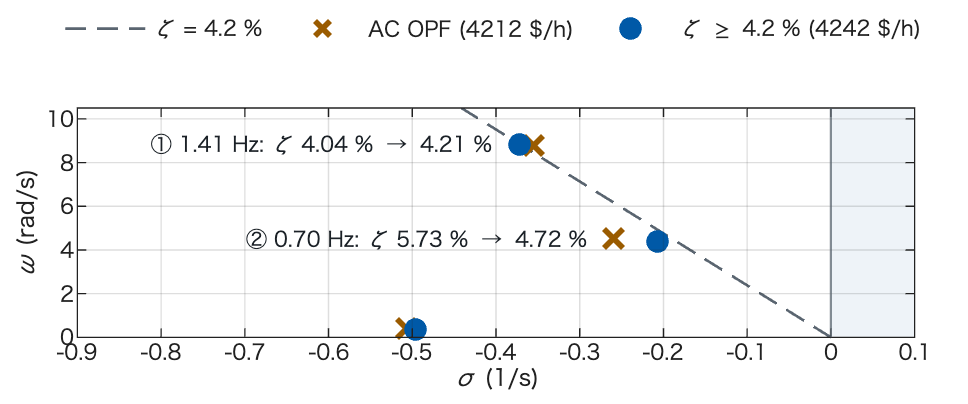

r_zmin = 0.042;
rr_xlim = [-0.9, 0.1];   % [1/s]
rr_ylim = [0, 10.5];     % [rad/s]
tab_free = resFree.sct_stability.tab_mode;
tab_stab = resStab.sct_stability.tab_mode;
tab_free = sortrows(tab_free(imag(tab_free.Eigenvalue) > 0, :), "Frequency", "descend");
tab_stab = sortrows(tab_stab(imag(tab_stab.Eigenvalue) > 0, :), "Frequency", "descend");
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
tl = tiledlayout(fig, 1, 1, Padding="compact");
ax = nexttile(tl);
set(ax, XLim=rr_xlim, YLim=rr_ylim, NextPlot="add", XGrid="on", YGrid="on", Box="on", Layer="top", FontSize=8);
patch(ax, [0, rr_xlim(2), rr_xlim(2), 0], rr_ylim([1, 1, 2, 2]), sct_style.rr_tint, ...
    EdgeColor="none", HandleVisibility="off");
xline(ax, 0, Color=sct_style.rr_muted, LineWidth=0.8, HandleVisibility="off");
plot(ax, -r_zmin / sqrt(1 - r_zmin^2) * rr_ylim, rr_ylim, "--", Color=sct_style.rr_muted, ...
    LineWidth=1, DisplayName=sprintf("\\zeta = %.1f %%", 100 * r_zmin));
plot(ax, real(tab_free.Eigenvalue), imag(tab_free.Eigenvalue), "x", Color=sct_style.rr_c3, ...
    MarkerSize=10, LineWidth=2, DisplayName=sprintf("AC OPF (%.0f $/h)", resFree.r_cost));
plot(ax, real(tab_stab.Eigenvalue), imag(tab_stab.Eigenvalue), "o", Color=sct_style.rr_brand, ...
    MarkerSize=7, LineWidth=1.5, MarkerFaceColor=sct_style.rr_brand, ...
    DisplayName=sprintf("\\zeta \\geq %.1f %% (%.0f $/h)", 100 * r_zmin, resStab.r_cost));
sr_mark = ["①", "②"];
for i_m = 1:2
    c_free = tab_free.Eigenvalue(i_m);
    c_stab = tab_stab.Eigenvalue(i_m);
    text(ax, min(real([c_free, c_stab])) - 0.03, mean(imag([c_free, c_stab])), ...
        sprintf("%s %.2f Hz: \\zeta %.2f %% \\rightarrow %.2f %%", sr_mark(i_m), ...
        tab_stab.Frequency(i_m), 100 * tab_free.DampingRatio(i_m), 100 * tab_stab.DampingRatio(i_m)), ...
        HorizontalAlignment="right", Color=sct_style.rr_ink);
end
xlabel(ax, "\sigma (1/s)");
ylabel(ax, "\omega (rad/s)");
lg = legend(ax, Orientation="horizontal", Box="off");
lg.Layout.Tile = "north";

**考察:** 主に G3 が揺れるモード ① は左へ動き、4.2% の線を越えました。主に G2 が揺れるモード ② の減衰は少し下がりますが、下限より上に残っています。OPF が守るのは「すべてのモードが下限以上」という条件だけで、モードの 1 つ 1 つを良くするわけではありません。出力の配分がどう変わったかも見ます。

P_free_MW = 100 * resFree.tab_cub{sv_gen, "P"}'    % [MW] 制約なし（G1, G2, G3）

P_free_MW =    89.7987  134.3206   94.1874


P_stab_MW = 100 * resStab.tab_cub{sv_gen, "P"}'    % [MW] ζ ≥ 4.2%

P_stab_MW =    90.7097  123.6939  104.1875


安い G2 の出力を約 11 MW 下げ、G3（と少し G1）に移すことで、モード ① の減衰を確保しています。G2 から遠くへ運ぶ電力が減り、送電線の負担のかかり方が変わるからです。その代わり、高い G3 の出力が増えた分だけ費用が上がります。

### 下限を上げるとどうなるか

下限を 6% に上げて、同じ計算をします。外側の反復の最大回数は既定の 10 回（`StabilityMaxIteration`）です。

resStab6 = net.calculate_optimal_powerflow(Method="AC OPF", MinDampingRatio=0.06);
resStab6.sct_stability.tab_iteration

ans = 10×7 table
    Iteration     Cost     MinDampingRatio    MaxRealPart               CriticalMode                    Step        Flag
    _________    ______    _______________    ___________    ___________________________________    ____________    ____

        1        4211.7       0.040396        -0.0072449     "B003SG1 1.4 Hz, B002SG1 0.72 Hz"       0.1    0.02     1  
        2        4254.2       0.041141        -0.0072784     "B003SG1 1.4 Hz, B002SG1 0.781 Hz"      0.1    0.02     1  
        3        4420.8       0.042107         -0.007272     "B003SG1 1.36 Hz, B002SG1 0.826 Hz"     0.1    0.02     1  
        4        4722.9       0.043216        -0.0072379     "B003SG1 1.33 Hz, B002SG1 0.857 Hz"     0.1    0.02     1  
        5        5161.1       0.044551        -0.0071685     "B003SG1 1.28 Hz, B002SG1 0.873 Hz"     0.1    0.02     1  
        6        5734.9       0.043863        -0.0070196     "B003SG1 1.29 Hz, B002SG1 0.868 Hz"    0.05    0.01     1  
        7     

2 つの計算の反復を、横軸を最小のダンピング比、縦軸を費用にして重ねます（知識ページの「安い運転と揺れやすさ」の図）。1 点が外側の反復 1 回で、どちらも制約なしの OPF（丸で囲んだ点）から始まります。外側の反復は表として返るので、`plot` で描きます。

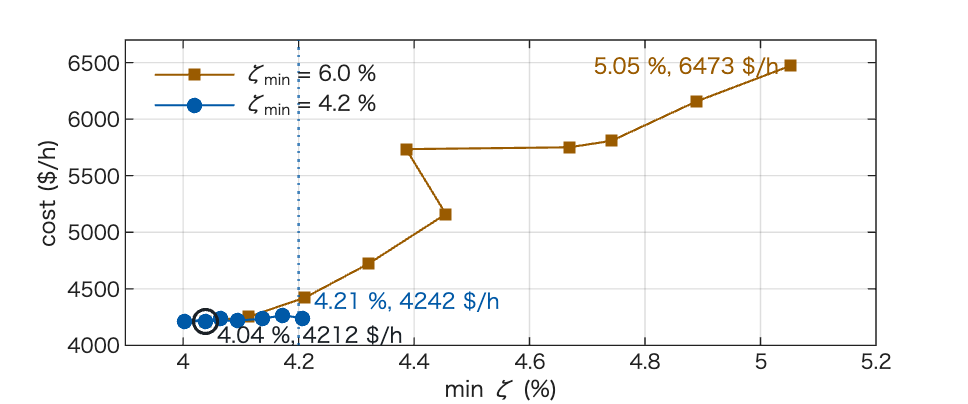

rr_zmin = [0.042, 0.06];
c_it = {resStab.sct_stability.tab_iteration, resStab6.sct_stability.tab_iteration};
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
ax = axes(fig, XLim=[3.9, 5.2], YLim=[4000, 6700], NextPlot="add", XGrid="on", YGrid="on", Box="on");
rm_colorIt = [sct_style.rr_brand; sct_style.rr_c3];
sr_marker = ["o", "s"];
for i_r = 2:-1:1
    tab = c_it{i_r};
    plot(ax, 100 * tab.MinDampingRatio, tab.Cost, "-" + sr_marker(i_r), Color=rm_colorIt(i_r, :), ...
        LineWidth=0.8, MarkerSize=5, MarkerFaceColor=rm_colorIt(i_r, :), ...
        DisplayName=sprintf("\\zeta_{min} = %.1f %%", 100 * rr_zmin(i_r)));
end
tab = c_it{1};
plot(ax, 100 * tab.MinDampingRatio(1), tab.Cost(1), "o", MarkerSize=9, Color=sct_style.rr_ink, ...
    LineWidth=1.2, HandleVisibility="off");
text(ax, 100 * tab.MinDampingRatio(1) + 0.02, tab.Cost(1) - 120, ...
    sprintf("%.2f %%, %.0f $/h", 100 * tab.MinDampingRatio(1), tab.Cost(1)), Color=sct_style.rr_ink);
text(ax, 100 * tab.MinDampingRatio(end) + 0.02, tab.Cost(end) + 150, ...
    sprintf("%.2f %%, %.0f $/h", 100 * tab.MinDampingRatio(end), tab.Cost(end)), Color=sct_style.rr_brand);
tab = c_it{2};
text(ax, 100 * tab.MinDampingRatio(end) - 0.02, tab.Cost(end), ...
    sprintf("%.2f %%, %.0f $/h", 100 * tab.MinDampingRatio(end), tab.Cost(end)), ...
    Color=sct_style.rr_c3, HorizontalAlignment="right");
xline(ax, 100 * rr_zmin(1), ":", Color=sct_style.rr_brand, LineWidth=1, HandleVisibility="off");
xlabel(ax, "min \zeta (%)");
ylabel(ax, "cost ($/h)");
legend(ax, Location="northwest", Box="off");

**考察:** 4.2% の計算（青）は、費用 +0.7% で条件を満たします。6% の計算（橙）は、反復のたびに費用が大きく増え、既定の 10 回の反復で 5.05% までしか届きません。そのときの費用は約 6473 $/h で、制約なしより約 54% 高くなります。おおむね、減衰を増やすほど費用がかかり、しかもその増え方は下限に近づくほど急になります。出力の配分を変えるだけで得られる減衰には限りがあるので、それ以上が必要なら PSS の調整など、制御器の側で減衰を増やす方が安く済みます（Part 8）。

**注意:**

- 安定度制約付き OPF は `"AC OPF"` だけで使え、系統を前もって `initialize` しておく必要があります。系統のモデルそのものは書き換えません。

- 決められた回数のうちに条件に届かないときは、`flag` が 0 になり、どこまで届いたかがメッセージに書かれます。`MaxRealPart` を指定すると、固有値の実部の上限も付けられます。

- 安定度制約付き OPF が扱うのは小さな外乱だけです。送電線の事故のような大きな外乱は過渡安定度の問題で、時間シミュレーション（Part 3）で確かめます。

## まとめ

- 経済負荷配分では、上下限に達していない発電機の増分費用がすべて等しくなります（等増分費用）。IEEE 9 母線系統では $\lambda \approx 24.0$ $/MWh で、手計算と GUILDA の答えが一致しました。

- AC OPF は電力方程式と運転の制約を加えます。費用の差（約 81 $/h）は、ほぼ損失（約 3.3 MW）をまかなう分でした。電圧は損失を減らすため上限に張り付きました。

- LMP は、その母線の負荷を 1 単位増やしたときの最小費用の増え方です。線路 7–8 が混雑すると価格が分かれ、B008 はどの発電機の増分費用よりも高くなりました。負荷を 1 MW 増やして解き直すと、G3 を上げて G2 を下げる組み替えが起き、費用の増え方が LMP と一致しました。

- いちばん安い運転点は減衰が小さいことがあります。安定度制約付き OPF は、OPF・線形化・固有値の感度からの制約を繰り返して、すべてのダンピング比を下限より上に保ちます。4.2% なら費用 +0.7% で済みますが、6% は届かず費用が 54% 増えました。

**次の Part:** Part 7「連続潮流計算と電力方程式のヤコビアン」では、負荷を少しずつ増やして PV カーブを描き、運転点のもう 1 つの静的な限界である電圧崩壊を扱います。

[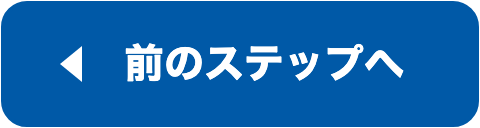](matlab:open('Part5_Linearization.mlx'))　　[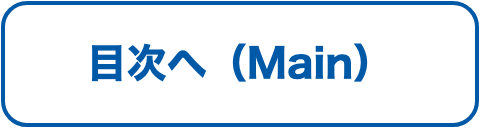](matlab:open('Main.mlx'))　　[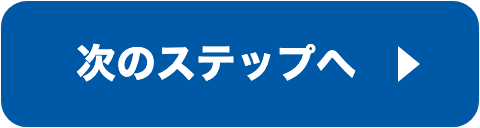](matlab:open('Part7_ContinuationPowerFlow.mlx'))